# EE230 HW1 MATLAB Question: Parameter Estimation

*İsmail Enes Bülbül, Abdullah Emir Göğüsdere*

*2442630, 2443075*

## Task: Estimating the probability of success from Bernoulli trials.

The Bernoulli random variable is a mathematical abstraction for a possibly unfair coin toss, expressed as follows:


$$X \in \{0, 1\} \qquad \text{P}(X = 1) = p,\,\,\, \text{P}(X = 0) = 1-p,\,\,\, p\in [0,1]$$


The $X=1$ case is called a *success*, and consequently $X=0$ is called as *failure*. In this work, you will be trying to estimate the probability of success $p$ of a Bernoulli random variable from `N` independent & identically distributed (iid.) samples. 

### Part I. Sampling

You will begin by using `randsample()` to take independent identically distributed (iid.) samples from the random variable described above. Think about discrete probabilistic model given above: What is the sample space, elementary events, and the assigned probabilities to these elementary events? How do they correspond to the arguments of `randsample()`?

- Assign a variable `N` for the number of samples, and adjust its value with a numeric slider that ranges from `10` to `1000` in steps of `10`. Have the control run the current section as its value is changing.

- Assign a variable `p` for the probability of success, and use a numeric slider to adjust its value.  Have the control run the current section as its value is changing.

- Use the function `randsample()` to generate `N` samples with probability of success `p`. Consult `help randsample` to figure out how the function works, if you need to. 

clear variables; close all; clc;
N = 1000;
p = 0.7;

samples = randsample([0 1],N,true,[1-p p]);

Now for some visualization.

- Use `histogram()` to plot how many of which outcome has been sampled. Prettify the plot.

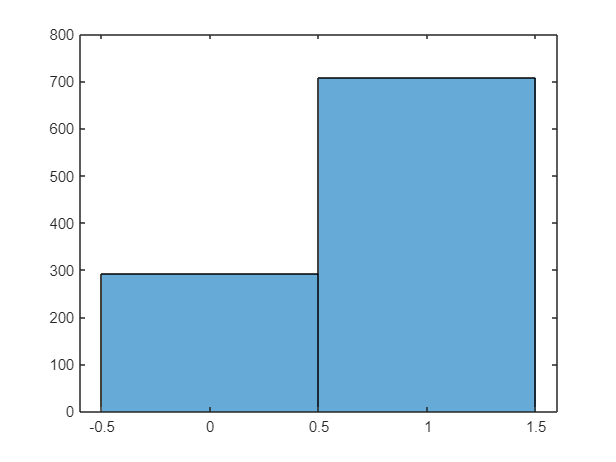

figure

histogram(samples)

### Part II. Estimation

Now that you have your samples, let's do some parameter estimation. You will try to estimate the probability of success via the most intuitive formula: Number of successes divided by the total number of trials.

- Use the previously generated samples and apply this formula to estimate the probability of success.

p_est = sum(samples(:) == 1)/N

p_est = 0.7080

What you code above is called an *estimator*: A function that maps the observed samples to the estimate of the quantitiy in question. You will want to convert your estimator to a stand-alone MATLAB function, so that it may be called when needed.

- Complete the empty function `estimator()` in Appendix A.1. and call it once more below to make sure it works.

p_est = estimator(samples)

p_est = 0.7080

### Part III. Evaluation

In this final part, you are asked to evaluate the success of your estimator as a function of number of observations. 

- Generate a new, "big" data set of `N = 1000` samples, again with `p` adjusted with a numeric slider.

- Write a `for` loop to use your estimator with the first `n` samples *of the dataset you generate in this section* where `n` varies from `1` to `N`, and record the estimator output to a vector.

- Plot the estimator output as a function of the number of observed samples. On the same plot, plot a horizontal line that is equal to the value of true `p`, so that it is easier to compare the estimated value to the true one.

- Have the final estimate of `p` and the true `p` printed in the title of the plot. This title must adapt to the final estimate and `p` value as set by the numeric slider. 

- Add a button control to rerun this section for a new data set of same size, and observe whether different estimated p vs. nr. of samples used converge to the same final `p` estimate. **Bonus:** Plot different realizations of these plot *on the same figure *multiple (5-10 should be plenty). If you do so, you can choose either run's final estimate to show in the title.

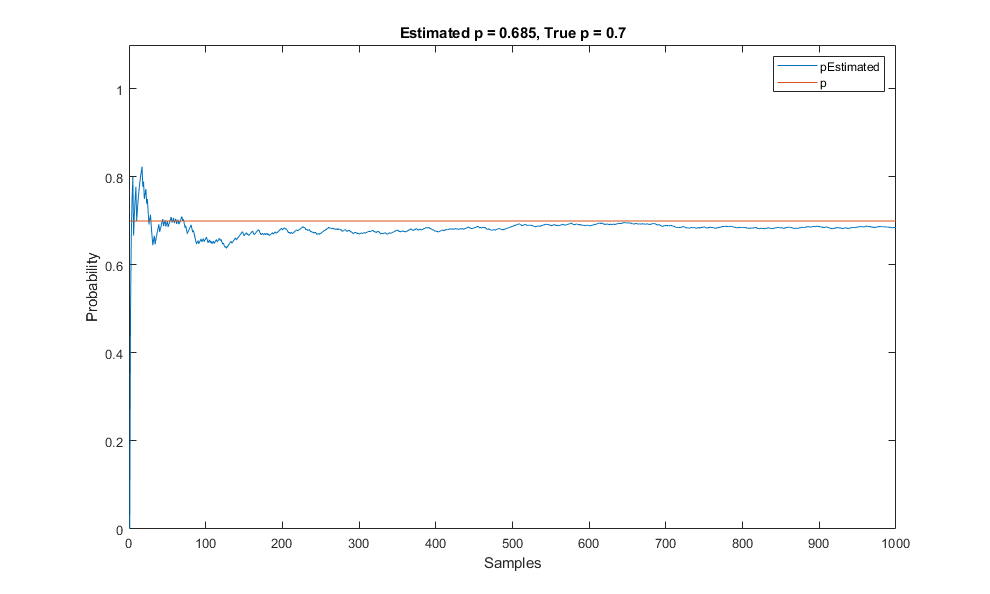

f = figure;
f.Position = [0 0 1000 600];

p = 0.7;
N = 1000;
data = randsample([0 1],N,true,[1-p p]);

p_est_ = ones(1,N);

for n = 1:N
    
    p_est_(n) = estimator(data(1,1:n));

end

plot(p_est_)
hold on;
plot(p*ones(1,N))

xlim([0 1000])
ylim([0 1.1])
legend("pEstimated", "p")
title("Estimated p = " + p_est_(1,N) + ", True p = " + p)
ylabel("Probability")
xlabel("Samples")

**Bonus:**

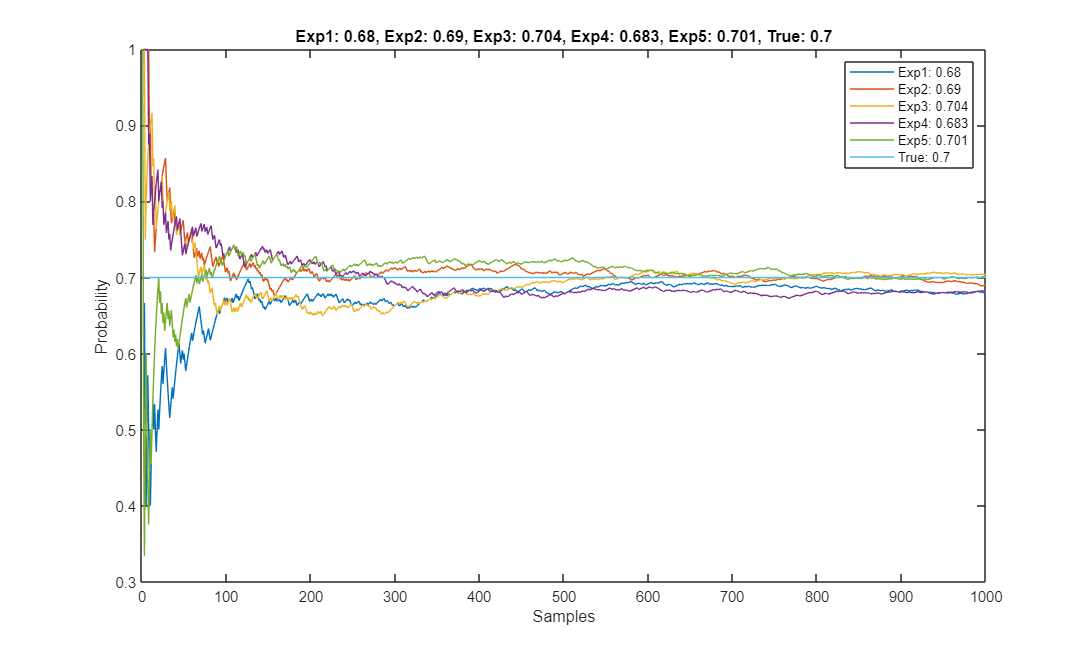

hold off; close all;
f = figure;
f.Position = [0 0 1000 600];

numExp = 5;
pEst = string(zeros(1,numExp));

for repeat = 1:numExp
    data = randsample([0 1],N,true,[1-p p]);
    
    p_est_ = ones(1,N);
    
    for n = 1:N
        
        p_est_(n) = estimator(data(1,1:n));
    
    end
    pEst(1,repeat) = "Exp" + ...
    string(repeat) + ": " + string(p_est_(1,N));

plot(p_est_)
hold on;

end

pEst = [string(pEst), "True: " + string(p)];
plot(p*ones(1,N))
title(join(pEst,", "))
legend(pEst)
ylabel("Probability")
xlabel("Samples")
hold off;

- Comment briefly on the behaviour you observe on the plot you create above. How does your estimator perform? Do the plots vary from run to run? What are the similarities and differences between different runs?

From the above plots, as we increase the portion of the **data** to be calculated in each loop until it reaches the whole portion, it can be seen that the **pEstimated** converges to the true **p**. Therefore, we can say that the **estimator** performs sufficiently. Moreover, we can see that the plots vary from run to run since the **randsample()** creates **N**-sized samples randomly and closely weighted to true **p**. 

The difference between runs is that the **data** sets in each run are created randomly and closely weighted to true p, so the data sets in each run are not the same. Although this is the case, their similarity is that their **pEstimated** will eventually converge to the true **p**.

## Appendix A. Function Declarations

### A.1. Your Estimator

function [p_est] = estimator(samples)
    [p_est] = sum(samples(:) == 1)/length(samples);
end